# Unique iterations of Common graphs

## Boxplot

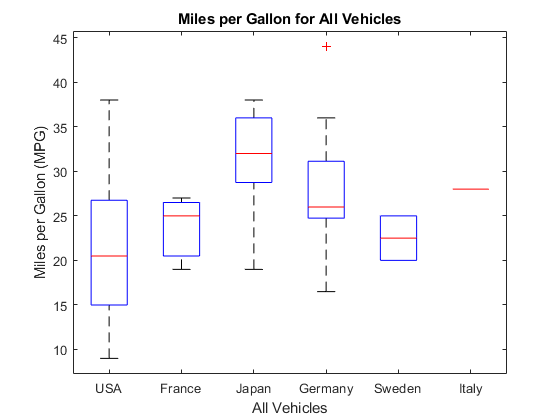

% Matlab has a fairly limited boxplot function
load carsmall
boxplot(MPG,Origin)
xlabel('All Vehicles')
ylabel('Miles per Gallon (MPG)')
title('Miles per Gallon for All Vehicles')

## Steps to build our own more versatile Boxplot

% 1. Load Data set
% 2. Create numerical elements needed for graphing
% 3. Use 'patch' and 'line' to build boxplot

## 1. Load Data set

% Load data set
load fisheriris.mat
% Create column names
% colnames = {'sepal_length', 'sepal_width', 'petal_length', 'petal_width'}; 
userData = meas;

## 2. Create numerical/statistical ingredients for boxplot

% Need boxplot ingredients
% 1. median
% 2. First Quartile
% 3. Third Quartile
% 4. Inter quartile range
% 5. Outlier limits
% 6. Outlier IDs

% % Set up the necessary elements

## Medians

medians = median(userData)

medians =     5.8000    3.0000    4.3500    1.3000


## Quartiles

% First quartile
fqrt = quantile(userData,0.25)

fqrt =     5.1000    2.8000    1.6000    0.3000


% Third quartile
tqrt = quantile(userData,0.75)

tqrt =     6.4000    3.3000    5.1000    1.8000


## Interquartile range

iqR = tqrt - fqrt

iqR =     1.3000    0.5000    3.5000    1.5000


## Outlier limits

maxOLim = tqrt + (iqR * 1.5) % Tukey's Boxplot Whisker 

maxOLim =     8.3500    4.0500   10.3500    4.0500


minOLim = fqrt - (iqR * 1.5)

minOLim =     3.1500    2.0500   -3.6500   -1.9500



maxWisk = max(userData);
minWisk = min(userData);

## Outlier IDs

% Create a LOGICAL matrix that contains placeholders for any values that should be considered outliers
outlierIDS = zeros(size(userData),'logical')

outlierIDS = 150×4 logical array
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0


for oi = 1:size(outlierIDS,2)
    
    tmpCol = userData(:,oi); % Select a column
    tmpMin = minOLim(oi);    % Get the minimum boundary
    tmpMax = maxOLim(oi);    % Get the maximum boundary
    
    % Use conditionals to find any point outside bounds
    outlierIDS(:,oi) = tmpCol > tmpMax | tmpCol < tmpMin
    
end

outlierIDS = 150×4 logical array
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0


outlierIDS = 150×4 logical array
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0


outlierIDS = 150×4 logical array
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0


outlierIDS = 150×4 logical array
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0
   0   0   0   0


sum(outlierIDS) % Check to make sure we found some outliers

ans =      0     4     0     0


## New Boxplot

% Loop through columns
clf
colorS = 'rgbk';
xAxisOffset = 0.25 % Jitter around x axis values

xAxisOffset = 0.2500

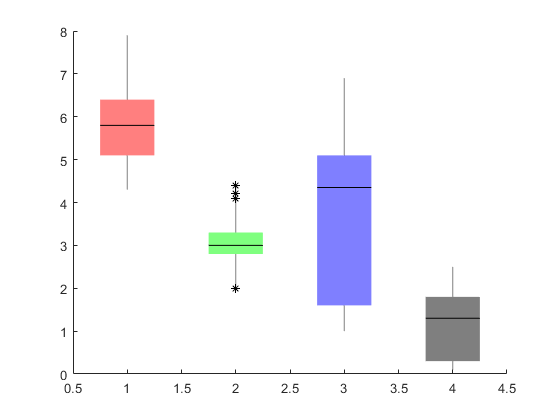

yVars =     5.1000    5.1000    6.4000    6.4000


p =   Patch with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


yVars =     2.8000    2.8000    3.3000    3.3000


p =   Patch with properties:

    FaceColor: [0 1 0]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


yVars =     1.6000    1.6000    5.1000    5.1000


p =   Patch with properties:

    FaceColor: [0 0 1]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


yVars =     0.3000    0.3000    1.8000    1.8000


p =   Patch with properties:

    FaceColor: [0 0 0]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×2 double]

  Show all properties


for boxI = 1:size(userData,2)
    
    % Create x-grid for patch
       % Counter clockwise starting in lower left corner
       % Center around integer
       % Four corners of box [bottom left , bottom right , top right , top left]
    xVars = [boxI - xAxisOffset boxI + xAxisOffset boxI + xAxisOffset boxI - xAxisOffset];
    % Create y-grid for patch
       % Must match order of x
       % 1. first quartile
       % 2. third quartile
       % Four corners of box [bottom left , bottom right , top right , top left]
    yVars =  [fqrt(boxI) fqrt(boxI) tqrt(boxI) tqrt(boxI)]
    
    % Put together in patch
    p = patch(xVars, yVars, colorS(boxI))
    p.FaceAlpha = 0.5; % Make it transparent - COOL!
    p.EdgeColor = 'none';
    % Add median
    hold on
    % To use the LINE function: 
       % First input = x values [start end]
       % Second input = y values [start end]
    line([boxI - xAxisOffset boxI + xAxisOffset] , [medians(boxI)  medians(boxI)], 'Color','k')
    % Add max and min lines
    % MAX
    line([boxI boxI] , [tqrt(boxI) maxWisk(boxI)], 'Color' , [0.5 0.5 0.5])
    % MIN
    line([boxI boxI] , [fqrt(boxI) minWisk(boxI)], 'Color', [0.5 0.5 0.5])
    
    % Add outliers
    plot(repmat(boxI,sum(outlierIDS(:,boxI)),1) , userData(outlierIDS(:,boxI),boxI),'k*')
 
end

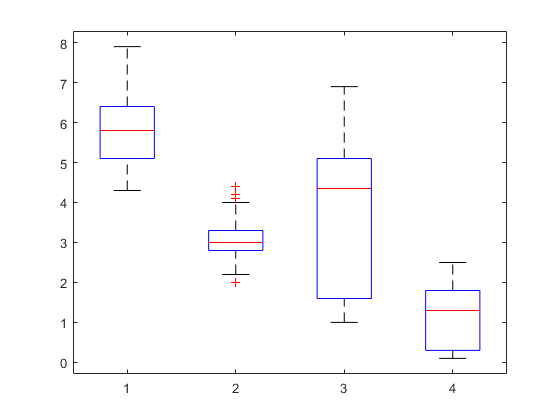

figure;
boxplot(userData)

## Ribbon plot

figure;
% Fake data
x = 0.1:0.1:10

x =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


y = sin(x)

y =     0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825   -0.9589


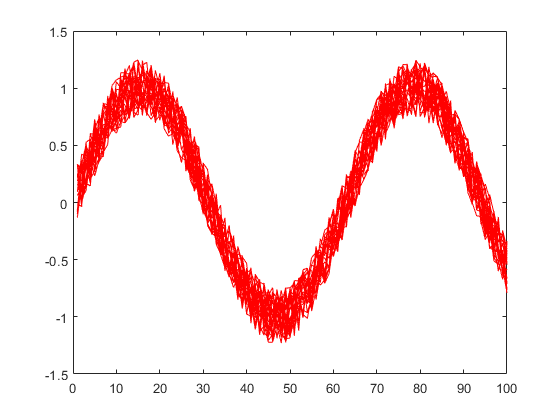


dataSet = transpose((((rand(25,length(y))*2)-1)/4) + repmat(y,25,1));
% Plot data
plot(dataSet,'r')

## Set up necessary plotting components

% 1. Mean
% 2. Upper Standard Deviation
% 3. Lower Standard Deviation

## Mean

% Derive mean for data sets
meanData = transpose(mean(dataSet,2))

meanData =     0.1686    0.1853    0.3017    0.3708    0.4894    0.5102    0.6104    0.7401    0.7872    0.8082    0.9084    0.9414    0.9558    0.9789    0.9905    0.9848    0.9674    0.9979    0.9058    0.9390    0.8666    0.8059    0.7623    0.6655    0.6629    0.5067    0.3889    0.3485    0.2213    0.0994    0.0033   -0.0482   -0.1654   -0.2889   -0.3839   -0.5005   -0.5503   -0.6241   -0.6761   -0.7187   -0.8461   -0.8500   -0.8901   -0.9390   -0.9820   -0.9974   -0.9466   -1.0031   -1.0014   -0.9608


## Standard Deviation

% Mean + SD: UPPER Bound
upperSD = meanData + transpose(std(dataSet,[],2))

upperSD =     0.3315    0.3266    0.4468    0.5082    0.6480    0.6405    0.7756    0.8512    0.9270    0.9375    1.0492    1.0900    1.1093    1.1280    1.1348    1.1218    1.1015    1.1336    1.0364    1.0443    0.9993    0.9402    0.8890    0.8179    0.7973    0.6635    0.5225    0.5123    0.3710    0.2514    0.1584    0.0995   -0.0237   -0.1600   -0.2460   -0.3567   -0.4301   -0.4796   -0.5244   -0.5924   -0.6961   -0.7055   -0.7216   -0.8138   -0.8256   -0.8428   -0.8293   -0.8681   -0.8496   -0.7989


% Mean - SD: LOWER Bound
lowerSD = meanData - transpose(std(dataSet,[],2))

lowerSD =     0.0056    0.0440    0.1566    0.2334    0.3309    0.3799    0.4452    0.6291    0.6473    0.6789    0.7676    0.7928    0.8022    0.8298    0.8461    0.8479    0.8333    0.8622    0.7751    0.8337    0.7339    0.6715    0.6356    0.5132    0.5286    0.3499    0.2553    0.1847    0.0716   -0.0526   -0.1517   -0.1959   -0.3071   -0.4177   -0.5218   -0.6442   -0.6705   -0.7686   -0.8278   -0.8451   -0.9960   -0.9945   -1.0585   -1.0642   -1.1384   -1.1520   -1.0639   -1.1380   -1.1531   -1.1228


## Construct plot

% Use 'patch' to create ribbon plot
% Remember to match x and y coordinates by wrapping around the entire object counter clockwise starting in lower left corner

% xVars: combine two elements - normal order x axis coordinates for lower bound AND flipped x axis coordinates for upper bound
lowerBoundX = 1:1:size(dataSet,1);
upperBoundX = fliplr(lowerBoundX);
xVars = [lowerBoundX , upperBoundX];

% yVars: almost similar to x
lowerBoundY = lowerSD

lowerBoundY =     0.0056    0.0440    0.1566    0.2334    0.3309    0.3799    0.4452    0.6291    0.6473    0.6789    0.7676    0.7928    0.8022    0.8298    0.8461    0.8479    0.8333    0.8622    0.7751    0.8337    0.7339    0.6715    0.6356    0.5132    0.5286    0.3499    0.2553    0.1847    0.0716   -0.0526   -0.1517   -0.1959   -0.3071   -0.4177   -0.5218   -0.6442   -0.6705   -0.7686   -0.8278   -0.8451   -0.9960   -0.9945   -1.0585   -1.0642   -1.1384   -1.1520   -1.0639   -1.1380   -1.1531   -1.1228


upperBoundY = fliplr(upperSD)

upperBoundY =    -0.3918   -0.3492   -0.2277   -0.1194   -0.0356    0.0124    0.1797    0.2965    0.3134    0.4935    0.5472    0.6821    0.7309    0.7844    0.8550    0.9951    1.0376    1.0732    1.1038    1.1201    1.1477    1.1758    1.0805    1.1848    1.1135    1.1215    0.9417    1.0268    0.9394    0.9027    0.8319    0.6976    0.6540    0.5856    0.3946    0.3789    0.2170    0.1597    0.0530   -0.1311   -0.1556   -0.2102   -0.3512   -0.4200   -0.4469   -0.6271   -0.6342   -0.6241   -0.6928   -0.7712


yVars = [lowerBoundY , upperBoundY]

yVars =     0.0056    0.0440    0.1566    0.2334    0.3309    0.3799    0.4452    0.6291    0.6473    0.6789    0.7676    0.7928    0.8022    0.8298    0.8461    0.8479    0.8333    0.8622    0.7751    0.8337    0.7339    0.6715    0.6356    0.5132    0.5286    0.3499    0.2553    0.1847    0.0716   -0.0526   -0.1517   -0.1959   -0.3071   -0.4177   -0.5218   -0.6442   -0.6705   -0.7686   -0.8278   -0.8451   -0.9960   -0.9945   -1.0585   -1.0642   -1.1384   -1.1520   -1.0639   -1.1380   -1.1531   -1.1228


## Patch ribbon plot

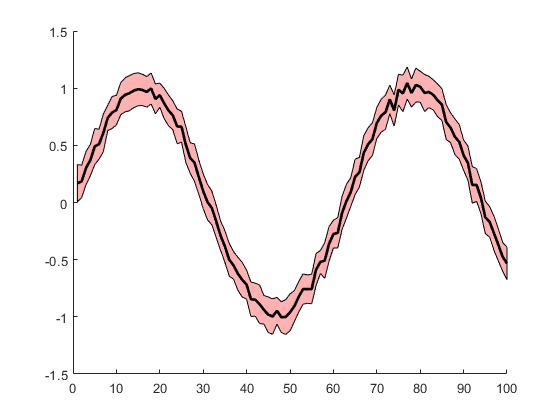

figure;
patch(xVars, yVars, 'r', 'FaceAlpha',0.3)

% Add mean line
hold on
plot(meanData,'k','LineWidth',2)